%% Rayleigh Noise Addition and Removal in Audio
% This script adds Rayleigh noise to an audio file and removes it using a
% low-pass filter to simulate everyday noise conditions.


%% Load the Original Audio File
% Load a sample audio file. Replace 'audio.wav' with your own file.
[audioIn, fs] = audioread('audio.wav');  % fs is the sampling rate
audioIn = audioIn(:, 1);  % Use only one channel if stereo

disp('Playing Original Audio...');

Playing Original Audio...


sound(audioIn, fs);
pause(length(audioIn)/fs + 1);

%% Add Rayleigh Noise to the Audio
% Generate Rayleigh noise with the same size as the audio signal
rayleighNoise = raylrnd(0.02, size(audioIn));  % Adjust scale (sigma) as needed

% Add the noise to the original audio
audioNoisy = audioIn + rayleighNoise;

% Normalize the noisy audio to prevent clipping
audioNoisy = audioNoisy / max(abs(audioNoisy));

disp('Playing Noisy Audio (Rayleigh Noise Added)...');

Playing Noisy Audio (Rayleigh Noise Added)...


sound(audioNoisy, fs);
pause(length(audioNoisy)/fs + 1);

%% Noise Removal using Low-Pass Filtering
% Apply a low-pass filter to remove high-frequency components introduced by noise
fc = 7000;  % Cut-off frequency (Hz) for the low-pass filter
Wn = fc / (fs / 2);  % Normalized frequency
[b, a] = butter(4, Wn, 'low');  % 4th order Butterworth filter

audioFiltered = filter(b, a, audioNoisy);

disp('Playing Denoised Audio...');

Playing Denoised Audio...


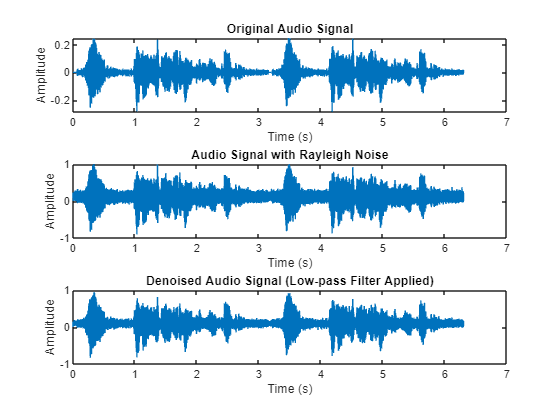

sound(audioFiltered, fs);
pause(length(audioFiltered)/fs + 1);

%% Plot the Signals for Comparison
t = (0:length(audioIn)-1) / fs;  % Time vector

figure;
subplot(3,1,1);
plot(t, audioIn);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, audioNoisy);
title('Audio Signal with Rayleigh Noise');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, audioFiltered);
title('Denoised Audio Signal (Low-pass Filter Applied)');
xlabel('Time (s)');
ylabel('Amplitude');


%% Save the Processed Audio Files (Optional)
audiowrite('noisy_audio.wav', audioNoisy, fs);
audiowrite('denoised_audio.wav', audioFiltered, fs);

disp('Audio processing complete. Files saved.');

Audio processing complete. Files saved.
